% IIR Filter from Manual Coefficients (Your Design)
clear; clc;

% Coefficients from your earlier H(z) calculation
b = [0.991, -1.862, 0.991];   % Numerator (feedforward)
a = [1, -1.866, 0.978];       % Denominator (feedback)

% Print the difference equation
fprintf('Your Calculated Difference Equation:\n');

Your Calculated Difference Equation:


fprintf('y[n] = %.3f*x[n] + %.3f*x[n-1] + %.3f*x[n-2] + %.3f*y[n-1] + %.3f*y[n-2]\n\n', ...
    b(1), b(2), b(3), -a(2), -a(3));

y[n] = 0.991*x[n] + -1.862*x[n-1] + 0.991*x[n-2] + 1.866*y[n-1] + -0.978*y[n-2]



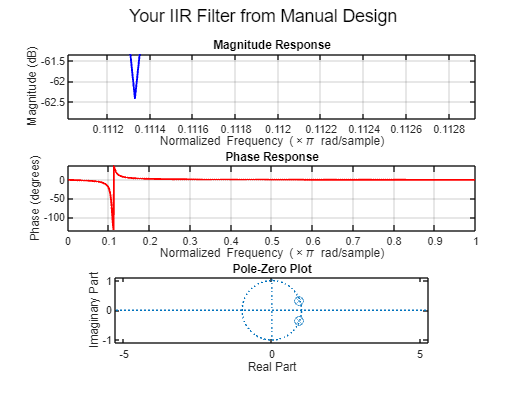


% Compute the frequency response
[h, w] = freqz(b, a, 1024); % 1024 points across normalized frequency (0 to π)
mag = 20*log10(abs(h));     % Convert magnitude to dB
phase = unwrap(angle(h)) * 180/pi;

% Plot responses
figure;
subplot(3,1,1);
plot(w/pi, mag, 'b', 'LineWidth', 1.5); grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Response');

subplot(3,1,2);
plot(w/pi, phase, 'r', 'LineWidth', 1.5); grid on;
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Phase (degrees)');
title('Phase Response');

subplot(3,1,3);
zplane(b, a);
title('Pole-Zero Plot');
sgtitle('Your IIR Filter from Manual Design');


% Optional: confirm pole locations
poles = roots(a);
zeros = roots(b);
fprintf('Poles: '); disp(poles.');

Poles:    0.9330 + 0.3279i   0.9330 - 0.3279i


fprintf('Zeros: '); disp(zeros.');

Zeros:    0.9395 + 0.3427i   0.9395 - 0.3427i


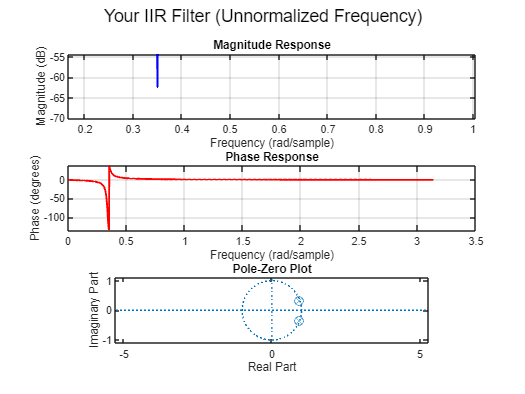

[h, w] = freqz(b, a, 1024); % w in radians/sample
mag = 20*log10(abs(h));
phase = unwrap(angle(h)) * 180/pi;

figure;
subplot(3,1,1);
plot(w, mag, 'b', 'LineWidth', 1.5); grid on;
xlabel('Frequency (rad/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Response');

subplot(3,1,2);
plot(w, phase, 'r', 'LineWidth', 1.5); grid on;
xlabel('Frequency (rad/sample)');
ylabel('Phase (degrees)');
title('Phase Response');

subplot(3,1,3);
zplane(b, a);
title('Pole-Zero Plot');
sgtitle('Your IIR Filter (Unnormalized Frequency)');

clear; clc;

A = 9;
wo = pi / A;                    
delta_w = A / 100;              
delta1 = A / 200;               
delta2 = A / 100;              
Delta_f = delta_w / pi;         

%% Step 1: Estimate M using Kaiser’s heuristic (from your slides)
M = ceil(((-20 * log10(delta1 * delta2)) - 13) / (14.6 * Delta_f) + 1);
N = M - 1;
fprintf('Calculated filter length M = %d\n', M);

Calculated filter length M = 85



%% Step 2: Use fir1 to design a linear-phase FIR notch filter
bw = delta_w;                          % Notch bandwidth in rad/sample
Wn = [(wo - bw/2), (wo + bw/2)] / pi;  % Normalized notch band (between 0 and 1)
h = fir1(N, Wn, 'stop', hamming(M));   % FIR notch filter using stopband spec

%% Step 3: Print the Difference Equation
fprintf('\nFIR Notch Filter Difference Equation:\n');


FIR Notch Filter Difference Equation:


fprintf('y[n] = ');

y[n] = 

for k = 1:length(h)
    fprintf('%.4f * x[n-%d]', h(k), k-1);
    if k < length(h)
        fprintf(' + ');
    end
end

0.0006 * x[n-0]

 + 

0.0002 * x[n-1]

 + 

-0.0002 * x[n-2]

 + 

-0.0007 * x[n-3]

 + 

-0.0013 * x[n-4]

 + 

-0.0018 * x[n-5]

 + 

-0.0022 * x[n-6]

 + 

-0.0024 * x[n-7]

 + 

-0.0023 * x[n-8]

 + 

-0.0017 * x[n-9]

 + 

-0.0007 * x[n-10]

 + 

0.0008 * x[n-11]

 + 

0.0026 * x[n-12]

 + 

0.0046 * x[n-13]

 + 

0.0063 * x[n-14]

 + 

0.0076 * x[n-15]

 + 

0.0079 * x[n-16]

 + 

0.0071 * x[n-17]

 + 

0.0051 * x[n-18]

 + 

0.0020 * x[n-19]

 + 

-0.0021 * x[n-20]

 + 

-0.0067 * x[n-21]

 + 

-0.0110 * x[n-22]

 + 

-0.0145 * x[n-23]

 + 

-0.0165 * x[n-24]

 + 

-0.0165 * x[n-25]

 + 

-0.0143 * x[n-26]

 + 

-0.0098 * x[n-27]

 + 

-0.0036 * x[n-28]

 + 

0.0038 * x[n-29]

 + 

0.0113 * x[n-30]

 + 

0.0180 * x[n-31]

 + 

0.0229 * x[n-32]

 + 

0.0252 * x[n-33]

 + 

0.0243 * x[n-34]

 + 

0.0203 * x[n-35]

 + 

0.0136 * x[n-36]

 + 

0.0048 * x[n-37]

 + 

-0.0049 * x[n-38]

 + 

-0.0142 * x[n-39]

 + 

-0.0219 * x[n-40]

 + 

-0.0270 * x[n-41]

 + 

0.9748 * x[n-42]

 + 

-0.0270 * x[n-43]

 + 

-0.0219 * x[n-44]

 + 

-0.0142 * x[n-45]

 + 

-0.0049 * x[n-46]

 + 

0.0048 * x[n-47]

 + 

0.0136 * x[n-48]

 + 

0.0203 * x[n-49]

 + 

0.0243 * x[n-50]

 + 

0.0252 * x[n-51]

 + 

0.0229 * x[n-52]

 + 

0.0180 * x[n-53]

 + 

0.0113 * x[n-54]

 + 

0.0038 * x[n-55]

 + 

-0.0036 * x[n-56]

 + 

-0.0098 * x[n-57]

 + 

-0.0143 * x[n-58]

 + 

-0.0165 * x[n-59]

 + 

-0.0165 * x[n-60]

 + 

-0.0145 * x[n-61]

 + 

-0.0110 * x[n-62]

 + 

-0.0067 * x[n-63]

 + 

-0.0021 * x[n-64]

 + 

0.0020 * x[n-65]

 + 

0.0051 * x[n-66]

 + 

0.0071 * x[n-67]

 + 

0.0079 * x[n-68]

 + 

0.0076 * x[n-69]

 + 

0.0063 * x[n-70]

 + 

0.0046 * x[n-71]

 + 

0.0026 * x[n-72]

 + 

0.0008 * x[n-73]

 + 

-0.0007 * x[n-74]

 + 

-0.0017 * x[n-75]

 + 

-0.0023 * x[n-76]

 + 

-0.0024 * x[n-77]

 + 

-0.0022 * x[n-78]

 + 

-0.0018 * x[n-79]

 + 

-0.0013 * x[n-80]

 + 

-0.0007 * x[n-81]

 + 

-0.0002 * x[n-82]

 + 

0.0002 * x[n-83]

 + 

0.0006 * x[n-84]

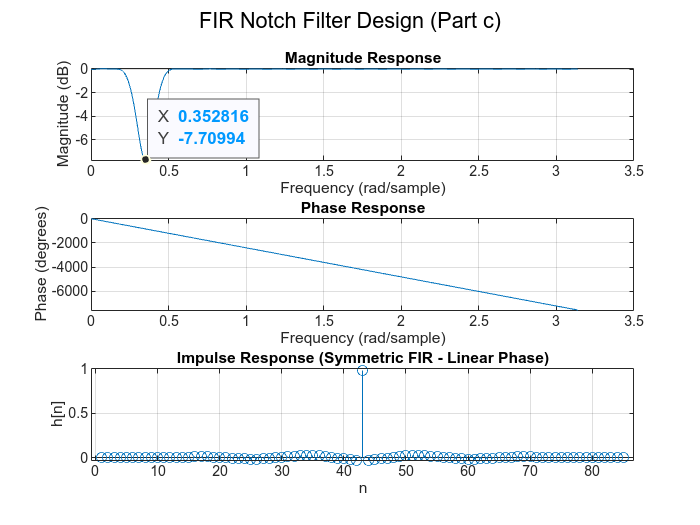

fprintf('\n');

%% Step 4: Implement using DF-I
x = randn(1, 1000);        % Example input signal
y_df1 = filter(h, 1, x);   % Direct Form I implementation

%% Step 5: Implement using DF-II
y_df2 = df2_fir(h, x);     % Custom Direct Form II implementation

%% Step 6: Frequency Response
[h_freq, w_freq] = freqz(h, 1, 1024);
mag = 20 * log10(abs(h_freq));
phase = unwrap(angle(h_freq)) * 180/pi;

%% Step 7: Plot results
figure;
subplot(3,1,1);
plot(w_freq, mag); grid on;
xlabel('Frequency (rad/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Response');

subplot(3,1,2);
plot(w_freq, phase); grid on;
xlabel('Frequency (rad/sample)');
ylabel('Phase (degrees)');
title('Phase Response');

subplot(3,1,3);
stem(h); grid on;
xlabel('n'); ylabel('h[n]');
title('Impulse Response (Symmetric FIR - Linear Phase)');

sgtitle('FIR Notch Filter Design (Part c)');

function y = df2_fir(h, x)
    N = length(h);
    y = zeros(size(x));
    w = zeros(1, N);
    for n = 1:length(x)
        w = [x(n), w(1:N-1)];
        y(n) = h * w.';
    end
end

